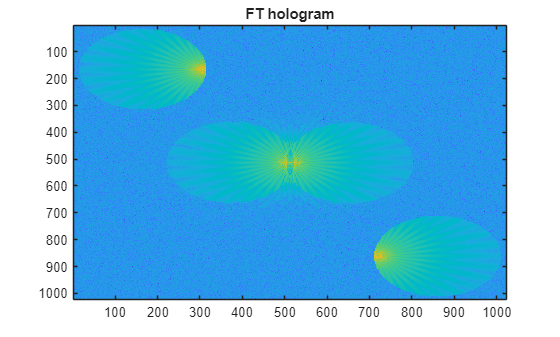

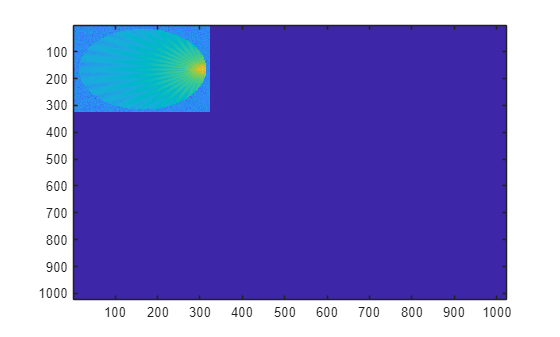

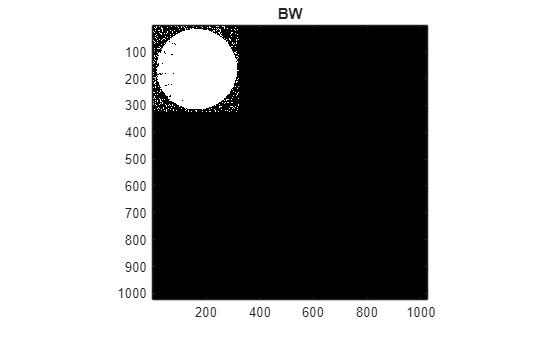

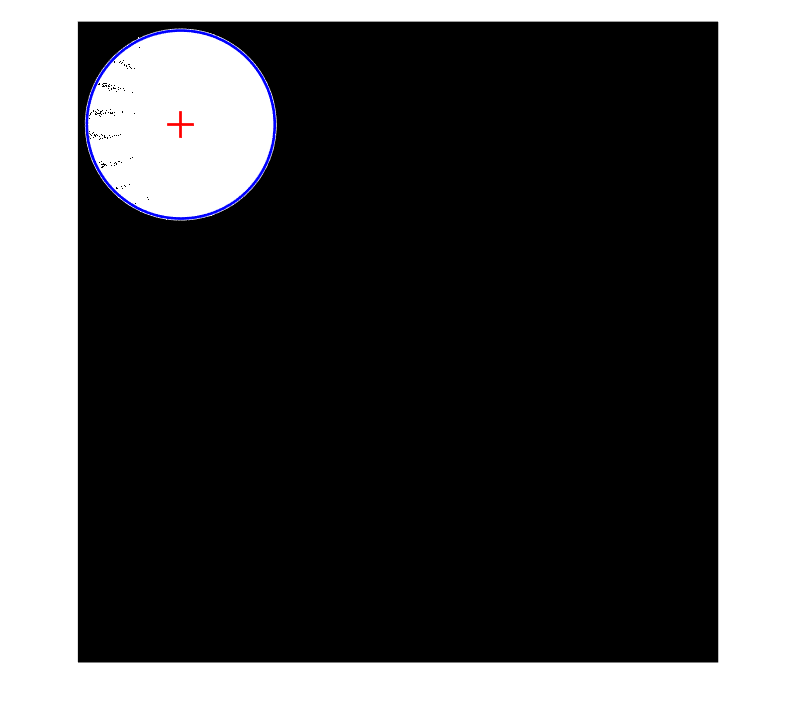

Centro detectado: (165.10, 164.98)
Radio detectado: 150.19 píxeles


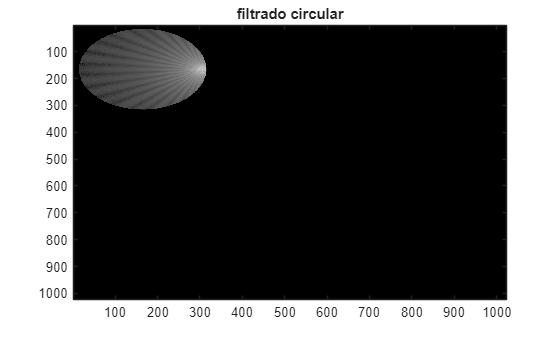

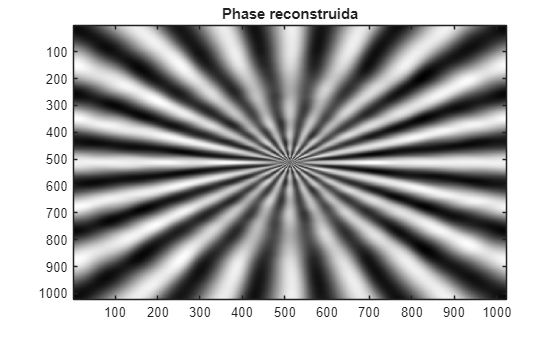

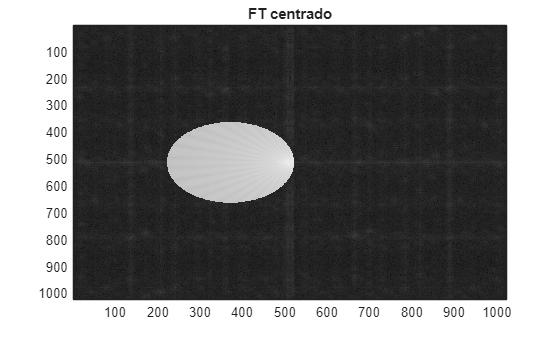

clc;
clear all;
close all;

[f,p] = uigetfile("*.bmp",MultiSelect="off");

file = strcat(p,f);
coplex = Ophase_rec(file,4.65,4.65,.532,2,0);

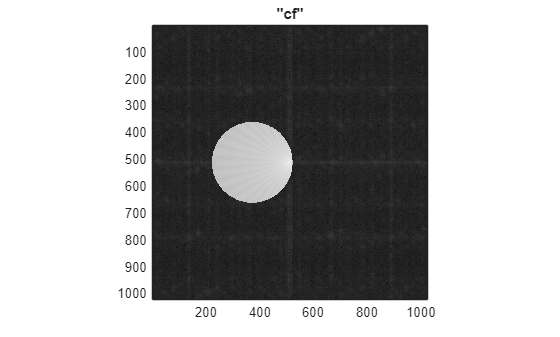


cf = FT(coplex);

figure; colormap gray;imagesc(log(abs(cf).^2));axis image;title "cf";


th = 12

th = 12

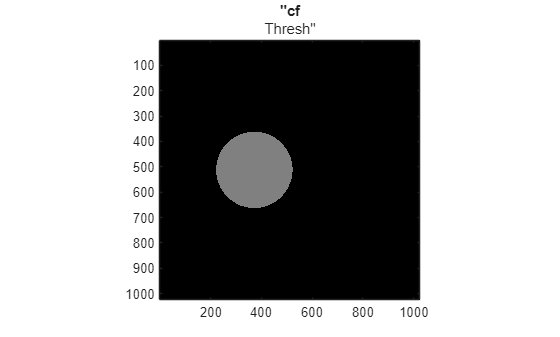


cfBW = imbinarize(log(abs(cf).^2));
figure; colormap gray;imagesc(log(abs(cfBW).^2));axis image;title "cf Thresh";